# Control de posición del variador-motor por realimentación de estados y asignación de polos

# 1. Estado del arte - realimentación de estados

Antes de realizar el controlador para la planta en el laboratorio es necesario realizar una contextualización de lo que es la realimentación de estados, observadores de estado de orden mínimo y el control de posición de un motor eléctrico.

## 1.1 Espacio de estados y realimentación de estados

El espacio de estados es la aproximación que se basa en el concepto de estado, concepto que ha existido durante mucho tiempo en la dinámica clásica y otros campos.

El estado de un sistema dinámico es el conjunto de variables más pequeño, de forma que el conocimiento de estas variables en t=t0, junto con el conocimiento de la entrada para t>=t0, determinan completamente el comportamiento del sistema en cualquier tiempo mayor a t0.

Las variables de estado son las variables que constituyen el menor conjunto de variables que determinan el estado del sistema dinámico. Si se necesitan n variables de estado para describir completamente el comportamiento de un sistema dado, entonces estas n variables de estado se pueden considerar las n componentes de un vector **x **(todo lo mencionado se especifica en  [2, pp. 29-31].

Para un sistema lineal e invariante en el tiempo:


$$\begin{array}{l}
{\dot{x} }_{\left(t\right)} =Ax_{\left(t\right)} +Bu_{\left(t\right)} \\
y_{\left(t\right)} =Cx_{\left(t\right)} +Du_{\left(t\right)} 
\end{array}$$


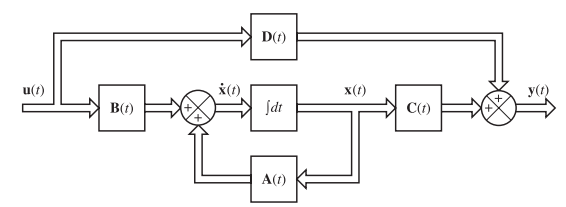

Para la realimentación de estados (problema de regulación) se selecciona la señal de control u determinada mediante el estado instantáneo:


$$u=-\mathrm{Kx}$$


La estabilidad y las características de respuesta transitoria se determinan mediante los valores característicos de la matriz A - BK. También, el sistema de control a lazo cerrado con la señal de control antes mencionada es:

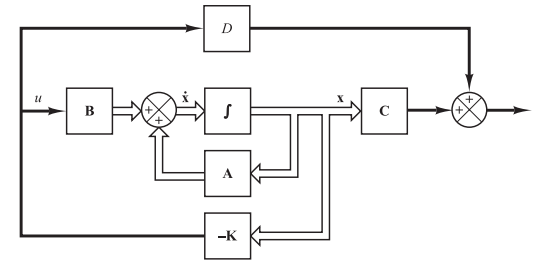

Los valores propios  de la matriz A - BK se denominan polos del regulador (todo esto se especifica en [2, pp. 723-725].

El problema de seguimiento se da cuando se pretende que la salida reproduzca asintóticamente a la referencia r(t) dada por la siguiente señal de control:


$$u\left(t\right)=\mathrm{Nr}\left(t\right)-\mathrm{Kx}\left(t\right)$$


Donde N es la ganancia de pre compensación y r(t) es la señal de referencia, el problema de regulación se da entonces cuando r(t)=0, es decir, que la referencia es nula.

El diagrama de bloques del problema de seguimiento es el siguiente:

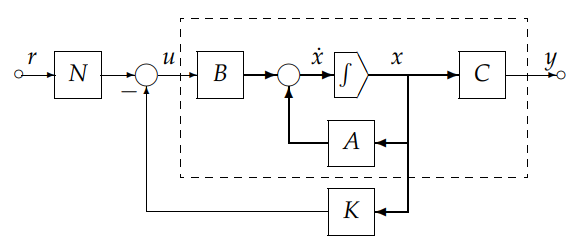

Se puede observar que el diagrama de bloques es muy similar al del problema de regulación y hace evidente que cuando r(t)=0 obtenemos el problema de regulación (todo esto se especifica en [1, pp. 144-151]).

Existe un problema con el esquema de seguimiento mostrado, este esquema no tiene un desempeño robusto, por lo que se requiere conocer la planta con exactitud para aplicar este esquema sin perder la característica de seguimiento [1, p. 152]. Es por ello que se introduce el esquema de seguimiento robusto de referencias constantes, el esquema se basa en aumentar la planta aumentando un nuevo estado que integra el error de seguimiento [1, p. 154]: 

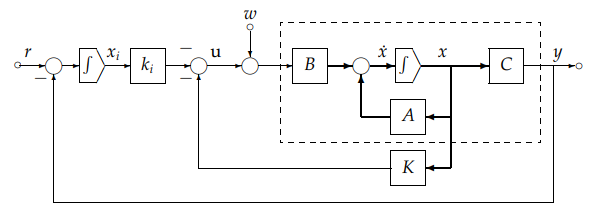

Este tipo de esquema se puede aplicar sobre plantas que ya contienen un integrador (plantas de tipo 1) [2, pp. 739-174], donde, con una elección adecuada de un conjunto de variables de estado es posible seleccionar la salida igual a una de las variables de estado, entonces la configuración general de este servosistema o servomecanismo cuando la planta tiene un integrador es la siguiente:

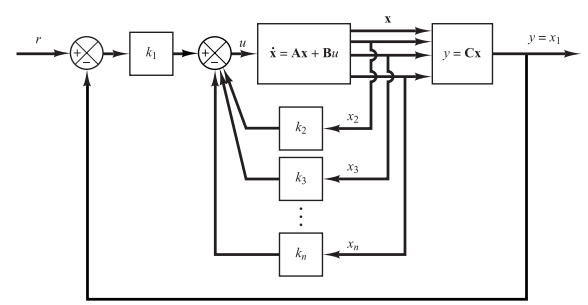

La señal de control es la siguiente:


$$u\left(t\right)=-\mathrm{Kx}\left(t\right)+k_1 r\left(t\right)$$


## 1.2 Observadores de estado

El control por realimentación de estados asume que hay disponibilidad de todas la variables de estado para ser realimentadas (se pueden medir), lo que en muchos casos es impráctico o directamente imposible, por lo que se debe diseñar un dispositivo dinámico llamado observador o estimador de estados, el cual tiene como salida una estimación del vector de estados, y tiene como entrada la señal de control u(t) y la salida del sistema y(t):

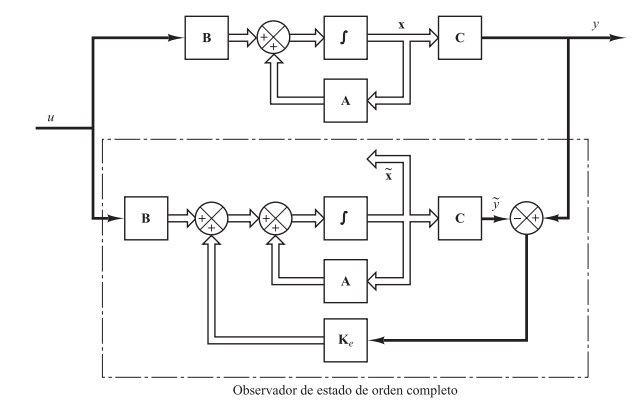

Donde la matriz Ke o matriz L, se llama matriz de ganancia del observador, es una matriz de ponderación al término de corrección que involucra la diferencia entre la salida medida y la salida estimada.

En la práctica, algunas variables de estado se pueden medir con precisión, en tales casos no es necesario estimar todas las variables de estado, es de este escenario que se introduce el observador de orden mínimo, donde **x** es un vector de dimensión n y el vector de salida es un vector de dimensión m medible. El observador de orden mínimo es uno de orden (n-m), el esquema es el siguiente:

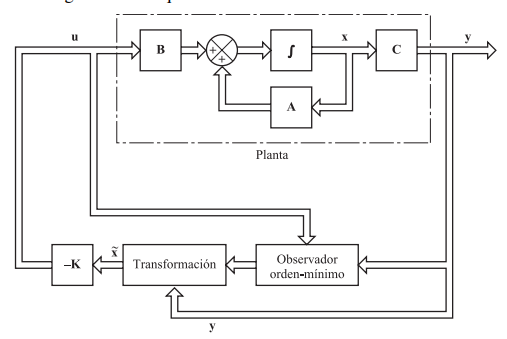

Además, se puede obtener una función basada en el observador de orden mínimo y así obtener un controlador basado en el observador y la realimentación de estados, teniendo finalmente un esquema como el que sigue (esto último es aplicado a sistema de una entrada y una salida o SISO):

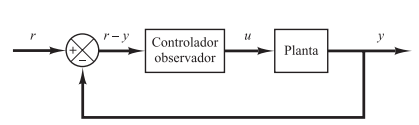

Todo lo tomado con referencia a los observadores se ha tomado de [1, pp. 156-162] y [2, pp. 751-787].

## 1.3 Control de posición

El control de posición que se va a aplicar será similar en la estructura de control (lazo cerrado) que se muestra en [3], la estructura que se muestra es la que sigue: 

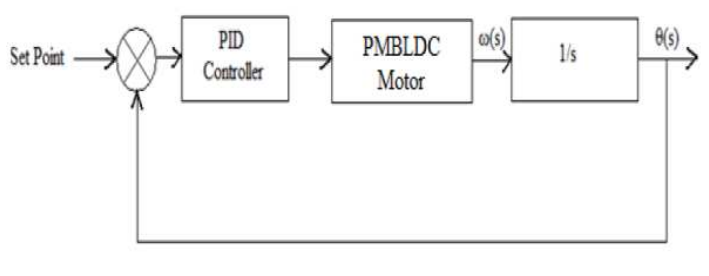

En esta estructura se muestra como controlador un PID, pero en esta ocasión ese bloque estará dado por el controlador-observador ya mostrado. Lo que se debe destacar de este esquema a lazo cerrado es que, al igual que en el caso que se va a abordar, la función de transferencia tiene como salida la velocidad angular y para poder realizar el control de posición se agrega un integrador a la salida de la función de transferencia que ya se tiene. También, hay que destacar que en [3] se controla un motor Brushless DC, pero se tiene ciertas similitudes con el caso que se va a tratar aquí, a continuación se muestra el esquema usado en [3]:

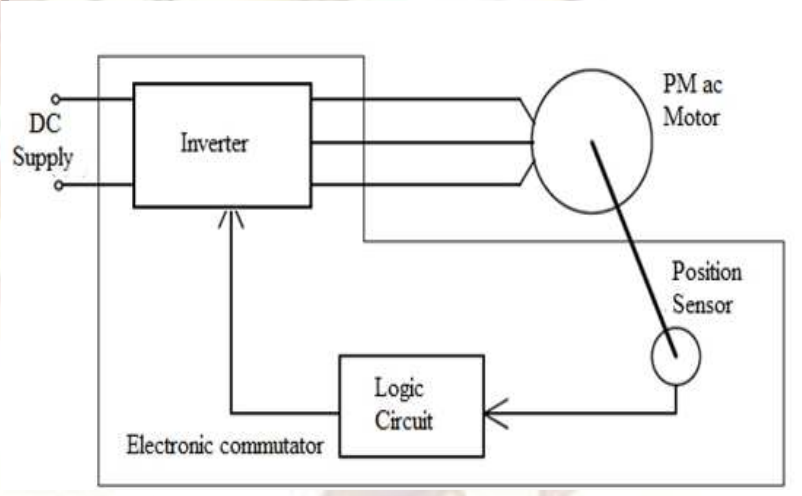

En el caso a tratar, el *Position Sensor* del esquema se trata de un encoder incremental, el bloque *Inverter* se trata en nuestro caso del variador de frecuencia (VFD), el *Logic Circuit* será en nuestro caso, si bien podría ser otra plataforma, se trata aquí específicamente de un PLC s7-200.

# 2. Modelo matemático de la planta y análisis

El modelo matemático de la planta se obtuvo de forma experimental. El modelo obtenido es una función de transferencia, donde se está suponiendo que el conjunto variador-motor es lineal y estacionario. El procedimiento por el cual se obtuvo el modelo se detalla en la bitácora de caracterización de la planta. Dicho modelo relaciona la velocidad angular (salida) del eje del motor y la tensión aplicada a la entrada analógica del variador de frecuencia (VFD).

## 2.1 Función de transferencia

Entrada de la función de transferencia experimental es voltaje y la salida velocidad angular [rad/seg]. La función que se obtuvo es como sigue:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\mathrm{rad}/\mathrm{seg}}{V}\right\rbrack$$


f_motor_rad=tf(26.55,[1 5.163 15.58])


f_motor_rad =
 
          26.55
  ---------------------
  s^2 + 5.163 s + 15.58
 
Continuous-time transfer function.



Se comprueba estabilidad BIBO, es decir, los polos deben tener parte real negativa:

pole(f_motor_rad)

ans =   -2.5815 + 2.9859i
  -2.5815 - 2.9859i


Queda así comprobado la estabilidad BIBO, con lo que la respuesta ante la entrada escalón debe tener respuesta en estado estacionario:

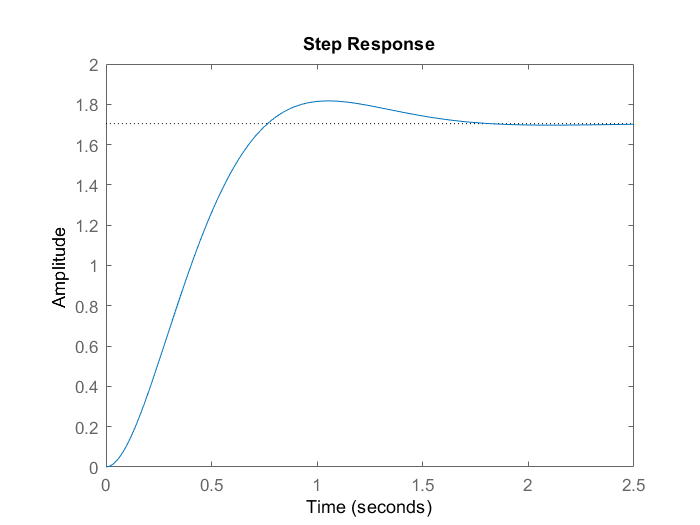

step(f_motor_rad)

La función de transferencia mostrada es una que relaciona la velocidad angular y el voltaje aplicado a la entrada del variador de frecuencia, sin embargo, para realizar un control de posición va a ser necesario obtener una función de transferencia que relaciona la posición y el voltaje de entrada. Para este propósito se parte de que la velocidad angular es la primera derivada de la posición angular:


$$\frac{\Omega \left(s\right)}{V\left(s\right)}=\frac{\Theta^˙ \left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^2 +5\ldotp 163*s+15\ldotp 58}\;\left\lbrack \frac{\mathrm{rad}/\mathrm{seg}}{V}\right\rbrack$$


Aplicando el teorema de diferenciación real de la transformada de Laplace se obtiene:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)-\theta \left(0\right)$$


Se va a considerar que las condición inicial de posición es cero, es decir, el proceso inicia con un ángulo de cero radianes:


$$\Theta^˙ \left(s\right)=s\Theta \left(s\right)$$


s=tf('s');  
pos_mot_rad=f_motor_rad/s


pos_mot_rad =
 
            26.55
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



De igual manera que antes, se comprueba la estabilidad BIBO:

pole(pos_mot_rad)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


En este caso no se comprueba estabilidad BIBO, por lo que ante una entrada escalón no se alcanzara el régimen permanente:

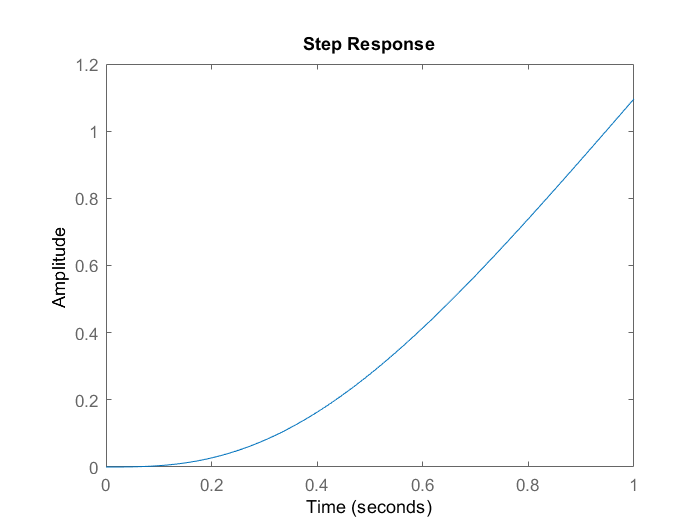

step(pos_mot_rad,1)

Se comprueba lo anteriormente dicho, sin embargo, este se trata de un sistema de tipo 1, por lo que se puede revisar el comportamiento en lazo cerrado con realimentación unitaria, donde podría estabilizarse y no tener error en estado estacionario:

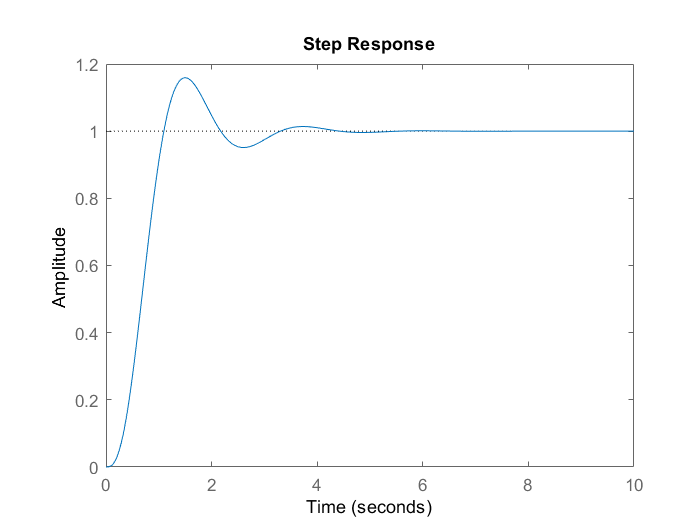

step(feedback(pos_mot_rad,1),10)

stepinfo(feedback(pos_mot_rad,1))

ans = struct with fields:
        RiseTime: 0.6615
    SettlingTime: 3.0580
     SettlingMin: 0.9144
     SettlingMax: 1.1592
       Overshoot: 15.9186
      Undershoot: 0
            Peak: 1.1592
        PeakTime: 1.5056


Lo último dicho se comprueba, además, a simple vista se puede suponer que no existe error en estado estacionario, y utilizando MATLAB se comprueba completamente:

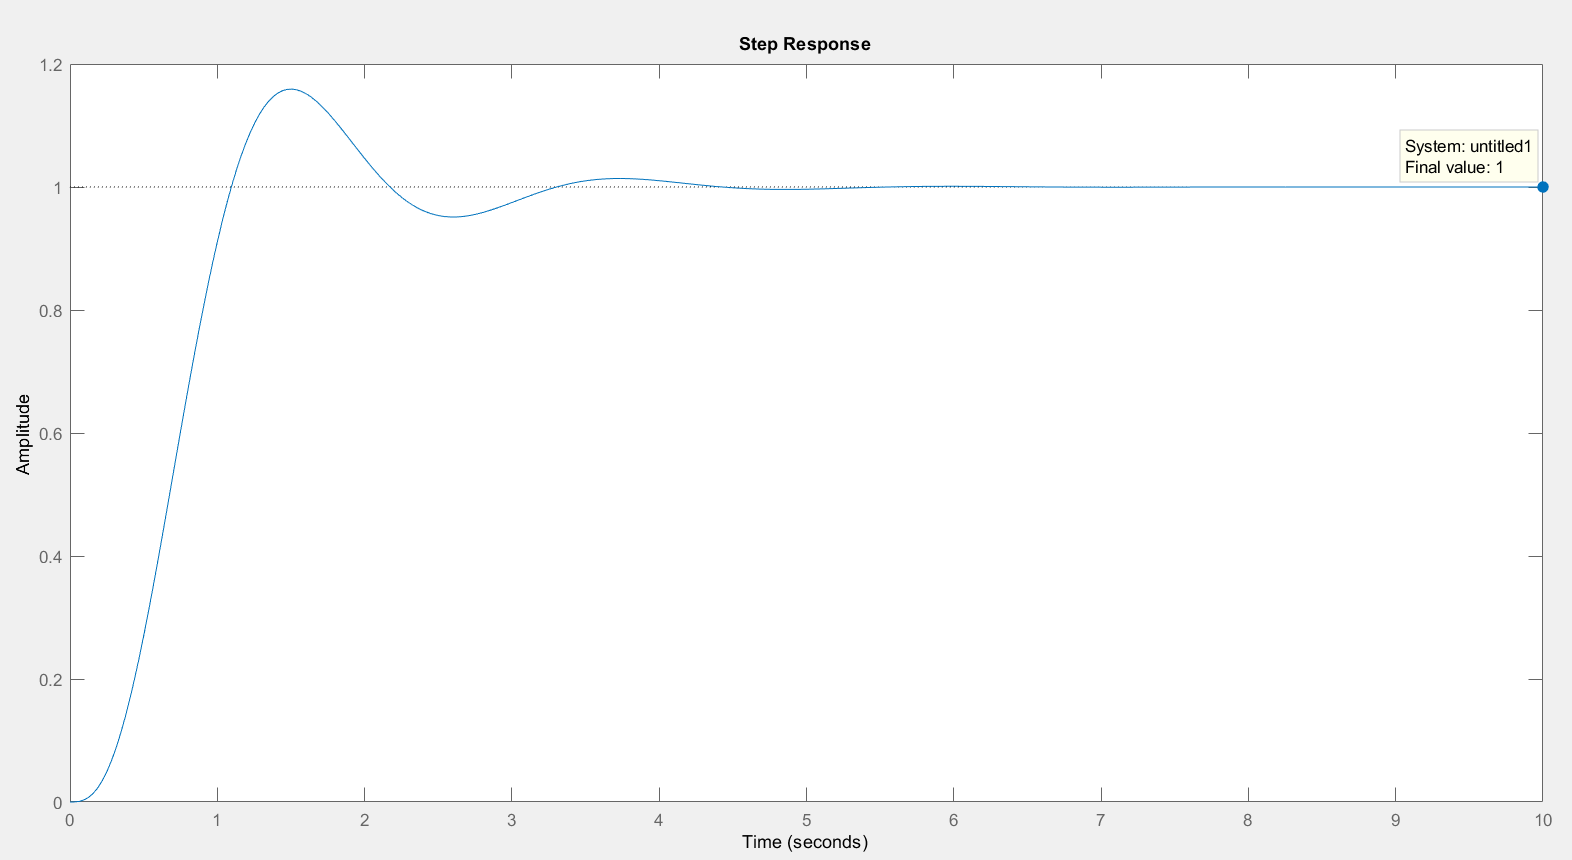

Esto nos dice que sobre esta planta se podría aplicar, más adelante, realimentación de estados con seguimiento robusto sin necesidad de agregar un integrador extra (servosistema tipo 1 con integrador en la planta)[1][2].

Hasta ahora se ha mostrado funciones de transferencia con unidades en radianes y la función que relaciona la posición, relaciona la posición angular. Pero, para los fines de la unidad de selección, es más útil tener una función de transferencia que relaciona la posición lineal, y que esta se encuentre en unidades que resulten fáciles de manejar, para esto último las unidades más sencillas de manejar son los centímetros.

Para poder relacionar la posición lineal de la cinta transportadora que se encuentra sobre eje del motor, se va a tener que suponer que no existen retardos de transporte (despreciables) sobre toda la cinta transportadora (suponer que esta es inextensible) y que la velocidad lineal del eje del motor es la misma velocidad que tendrá la cinta. Con estas suposiciones podemos decir que la longitud de arco del eje del motor y el desplazamiento de la cinta transportadora son idénticos.

Sabiendo que la longitud de arco es igual a:


$$L=r\;\theta$$


Se debe determinar el radio del eje del motor que está sujeto a la cinta transportadora, realizando mediciones simples se puede aproximar el radio a:


$$r=1\ldotp 8382\;\left\lbrack \mathrm{cm}\right\rbrack$$


Por lo tanto, aplicando la ecuación de la longitud de arco sobre la función de transferencia:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{26\ldotp 55}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}*1\ldotp 8382\left\lbrack \frac{\textrm{cm}}{V}\right\rbrack$$


pos_mot=pos_mot_rad*1.8382


pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



Como tal, se está aplicando un escalamiento adecuándose la función de transferencia mediante la ecuación lineal de longitud de arco y con las unidades que queremos manejar (centímetros), por lo cual las características dinámicas no se ven alteradas más allá de la ganancia de la función de transferencia.

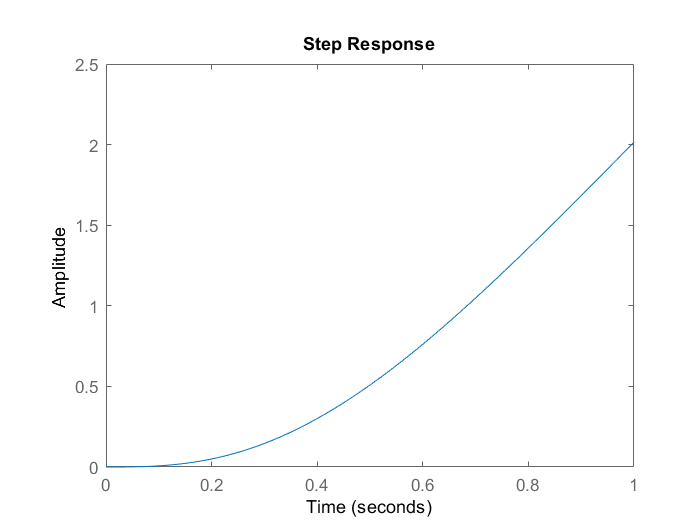

step(pos_mot,1)

## 2.2 Modelo en el espacio de estados 

Para hallar el modelo en espacio de estados podemos partir de la ecuación diferencial lineal estacionaria que modela al sistema a partir de la función de transferencia obtenida:


$$\frac{L\left(s\right)}{V\left(s\right)}=\frac{48\ldotp 8042}{s^3 +5\ldotp 163*s^2 +15\ldotp 58*s}$$


Por comodidad:


$$\begin{array}{l}
a=48\ldotp 8042\\
b=5\ldotp 1630\\
c=15\ldotp 58\\
\frac{L\left(s\right)}{V\left(s\right)}=\frac{a}{s^3 +b*s^2 +c*s}
\end{array}$$


## 
$${\overset{\ldotp \ldotp \ldotp }{l} }_{\left(t\right)} +b*{\overset{\ldotp \ldotp }{l} }_{\left(t\right)} +c*{\overset{\ldotp }{l} }_{\left(t\right)} =a*v_{\left(t\right)}$$


Eligiendo las variables de estado como:


$$\begin{array}{l}
x_1 =l_{\left(t\right)} \;\;\mathrm{Posición}\\
x_2 ={\dot{l} }_{\left(t\right)} \;\;\mathrm{Velocidad}\\
x_3 ={\overset{\ldotp \ldotp }{l} }_{\left(t\right)} \;\;\mathrm{Aceleración}
\end{array}$$


El modelo en variables de estado queda como:


$${\dot{x} }_{\left(t\right)} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -c & -b
\end{array}\right\rbrack x_{\left(t\right)} +\left\lbrack \begin{array}{c}
0\\
0\\
a
\end{array}\right\rbrack v_{\left(t\right)}$$



$${\dot{x} }_{\left(t\right)} =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
0 & -15\ldotp 58 & -5\ldotp 163
\end{array}\right\rbrack x_{\left(t\right)} +\left\lbrack \begin{array}{c}
0\\
0\\
48\ldotp 8042
\end{array}\right\rbrack v_{\left(t\right)}$$


[num,den]=tfdata(pos_mot);
num=cell2mat(num);
den=cell2mat(den);
a=num(4)

a = 48.8042

b=den(2)

b = 5.1630

c=den(3)

c = 15.5800


A=[0 1 0
   0 0 1
   0 -c -b]

A =          0    1.0000         0
         0         0    1.0000
         0  -15.5800   -5.1630


B=[0
   0
   a]

B =          0
         0
   48.8042


C=[1 0 0]

C =      1     0     0



D=[0]

D = 0

En este caso se puede realizar el análisis de estabilidad interna, se puede aplicar la función de Lyapunov para sistemas lineales o, como en este caso, revisar el valor de los autovalores de la matriz A, los que deben tener parte real negativa:

eig(A)

ans =    0.0000 + 0.0000i
  -2.5815 + 2.9859i
  -2.5815 - 2.9859i


En este caso no se comprueba la estabilidad interna, esto se puede evidenciar que al revisar la respuesta ante condiciones iniciales distintas de cero (y sin entrada de excitación externa) el estado x1 (posición) no tiene asintóticamente a cero, al contrario los estados de velocidad y aceleración que si tienden asintóticamente a cero. Entonces, con el control que se aplique se debe procurar estabilizar al sistema.

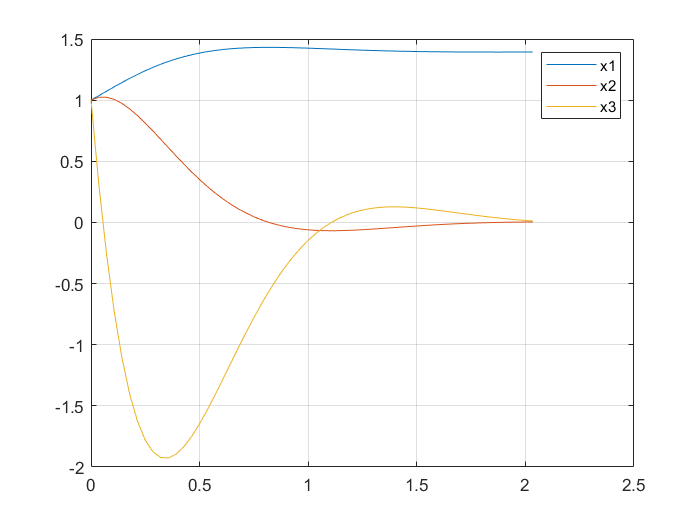

[y,t,x]=initial(ss(A,B,C,D),[1 1 1]');
plot(t,x(:,1))
hold on
plot(t,x(:,2))
plot(t,x(:,3))
hold off
grid on
legend('x1','x2','x3')

# 3. Control por realimentación de estados 

## 3.1 Ley de control

Se va a utilizar el control por realimentación de estados, inicialmente partimos de la ley de control para un sistema seguidor:


$$u_{\left(t\right)} =Nr_{\left(t\right)} -Kx_{\left(t\right)}$$


Pero, como ya se adelantó, al tratarse de un sistema de tipo 1, se puede utilizar una ley de control para un sistema de seguimiento robusto y sin necesidad de agregar un estado extra (integrador):


$$u_{\left(t\right)} =k_1 r_{\left(t\right)} -Kx_{\left(t\right)}$$


Donde:


$$K=\left\lbrack \begin{array}{ccccc}
k_1  & k_2  & k_3  & \ldotp \ldotp \ldotp  & k_n 
\end{array}\right\rbrack$$


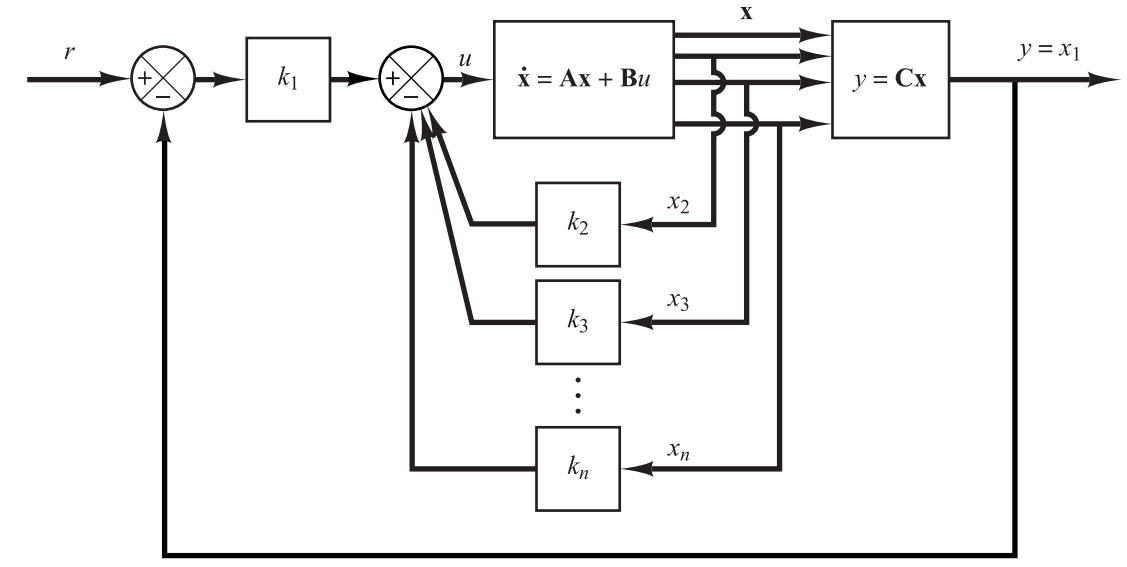

Para hallar la matriz de ganancia de realimentación de estado se utilizara el metodo de asignacion de polos.

## 3.2 Determinación de la matriz de ganancia de realimentación de estado 

En este caso, los requerimientos temporales de la respuesta del sistema a lazo cerrado no son estrictos y son en cierta medida arbitrarios, únicamente se debe tener en cuenta que existe la no-linealidad de la saturación por parte de la entrada anlogica del variador de frecuencia que va desde los 0V hasta los 10V. De cualquier manera, no se necesita que la unidad de selección funcione a una alta velocidad, ya que el intervalo entre el depósito de piezas cilíndricas está en el orden de los minutos. Entonces se elige un tiempo de asentamiento adecuado para la cinta de 4 [seg] al 2%, y además se elige una respuesta que no tenga sobre picos, esto último ya que no sería deseable que la posición de las piezas al momento de ser transportadas en la cinta tenga oscilaciones, ya que podría ser malinterpretado por los sensores (interruptores discretos) de que se ha llegado a la posición requerida.

Se parte de la respuesta de un sistema de segundo orden para determinar la posición de los polos dominantes para obtener el tiempo de asentamiento que queremos.

ts=4;       %tiempo de asentamiento
zeta_d=1.3; %sobre amortiguado
wn_d=3.3*2*zeta_d/ts

wn_d = 2.1450


Gd=wn_d^2/(s^2+2*zeta_d*wn_d*s+wn_d^2) %sistema de segundo orden


Gd =
 
          4.601
  ---------------------
  s^2 + 5.577 s + 4.601
 
Continuous-time transfer function.



p=pole(Gd);
stepinfo(Gd)

ans = struct with fields:
        RiseTime: 2.2726
    SettlingTime: 4.1330
     SettlingMin: 0.9005
     SettlingMax: 0.9998
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9998
        PeakTime: 8.6455


Entonces los polos dominantes deseados serán -4.5703 y -1.0067 y definiremos el tercer polo que se debe asignar lo suficientemente alejado de estos polos para que sus efectos sobre la respuesta transitoria sean despreciables, se lo definirá en -15.

Para poder asignar estos polos, el sistema debe ser de estado completamente controlable, por lo que se obtiene la matriz de controlabilidad:

%Controlabilidad
C_cont=[B A*B A^2*B]

C_cont =          0         0   48.8042
         0   48.8042 -251.9761
   48.8042 -251.9761  540.5832


rank(C_cont)

ans = 3

Se puede observar que la matriz de controlabilidad es de rango pleno, por lo tanto es controlable.

Existen varios métodos para determinar como tal la matriz de ganancia de realimentación de estados, en este caso se opta por usar la formula de Ackermann

%Ecuacion caracteristica con los polos deseados
p

p =    -4.5703
   -1.0067


H=conv([1 -p(1)],[1 -p(2)]);
H=conv(H,[1 15])

H =     1.0000   20.5770   88.2560   69.0154


%Formula de Ackermann
phi=H(1)*A^3+H(2)*A^2+H(3)*A+H(4)*eye(3)

phi =    69.0154   72.6760   15.4140
         0 -171.1347   -6.9065
         0  107.6026 -135.4767


K=[0 0 1]*inv(C_cont)*phi

K =     1.4141    1.4891    0.3158


Con la ganancia K obtenida, se puede realizar una simulación de la respuesta con la realimentación de estados, para revisar si se cumplen las características deseadas de la respuesta transitoria y de la respuesta de régimen permanente.

%simulacion (sin observador)
sys=ss(A-B*K,B*K(1),C,D)


sys =
 
  A = 
           x1      x2      x3
   x1       0       1       0
   x2       0       0       1
   x3  -69.02  -88.26  -20.58
 
  B = 
          u1
   x1      0
   x2      0
   x3  69.02
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



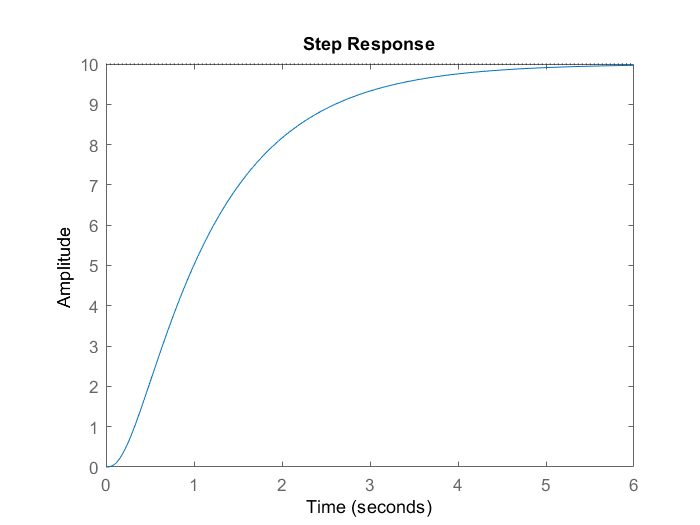

step(10*sys)

stepinfo(sys)

ans = struct with fields:
        RiseTime: 2.2794
    SettlingTime: 4.2021
     SettlingMin: 0.9016
     SettlingMax: 0.9986
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9986
        PeakTime: 6.8318


Como se observa, el tiempo de asentamiento es de aproximadamente 4 [seg] al 2% (es un poco superior, 4.2 [seg], pero como se mencionó anteriormente, los requerimientos temporales no son estrictos), y no se tiene error en estado estacionario (esto al ser un sistema de seguimiento robusto).

## 3.3 Diseño del observador de estado

En la práctica, suele ser complicado o directamente imposible medir todos los estados de la planta, en este caso podríamos medir velocidad o posición con el encoder incremental con el que se cuenta, pero no se puede medir la aceleración tan fácilmente, por lo que se optara por utilizar un observador de estado. Además, se va a optar por un observador de estado de orden reducido, esto porque se puede medir de forma efectiva la posición y no es realmente necesario estimar esta variable de estado. 

Para ello se debe revisar que el sistema sea observable, para ello se obtiene la matriz de observabilidad

%observabilidad
C_obs=[C' A'*C' A'^2*C']

C_obs =      1     0     0
     0     1     0
     0     0     1


rank(C_obs)

ans = 3

Y que la matriz de observabilidad de rango pleno, el sistema es observable.

Para hallar la matriz de ganancia del observador de orden reducido, se parte de las ecuaciones de estado particionado (estados medibles y no medibles) como:

Aaa=A(1,1)

Aaa = 0

Aab=A(1,2:3)

Aab =      1     0


Aba=A(2:3,1)

Aba =      0
     0


Abb=A(2:3,2:3)

Abb =          0    1.0000
  -15.5800   -5.1630


Ba=[0];
Bb=B(2:3);

La matriz de ganancia se puede hallar a partir de estas matrices, tal como antes, se va a optar por utilizar la fórmula de Ackermann para hallar la matriz de ganancias del observador. Los polos del observador no tienen algún criterio especial para su elección en este punto, por lo que mediante prueba y error se encuentran los polos del observador que menos afectan la respuesta transitoria del sistema observador-controlador.

%Formula de Ackermann
phi_1=[1 5];     %polos del observador
phi=conv(phi_1,phi_1)

phi =      1    10    25


Ke=(phi(1)*Abb^2 + phi(2)*Abb + phi(3)*eye(2))*inv([Aab;Aab*Abb])*[0;1]

Ke =     4.8370
  -15.5534


Ka=K(1);
Kb=K(2:3);

Se tiene la matriz de ganancias del observador y la matriz de ganancia de realimentación de estados, entonces, se puede hallar la función de transferencia del controlador basado en observador de orden mínimo.

%Funcion de transferencia Controlador-observador
Ahat= Abb - Ke*Aab;
Bhat= Ahat*Ke + Aba - Ke*Aaa;
Fhat=Bb - Ke*Ba;
Atilde=Ahat - Fhat*Kb;
Btilde=Bhat - Fhat*(Ka + Kb*Ke);
Ctilde=-Kb;
Dtilde=-(Ka + Kb*Ke);
[num,den]=ss2tf(Atilde,Btilde,-Ctilde,-Dtilde)

num =     3.7048    4.3676   35.3532


den =     1.0000   25.4140  172.2335


controlador=tf(num,den)


controlador =
 
  3.705 s^2 + 4.368 s + 35.35
  ---------------------------
     s^2 + 25.41 s + 172.2
 
Continuous-time transfer function.



Se debe asegurar que el controlador como tal no sea inestable, por lo que:

pole(controlador)

ans =  -12.7070 + 3.2811i
 -12.7070 - 3.2811i


zero(controlador)

ans =   -0.5895 + 3.0323i
  -0.5895 - 3.0323i


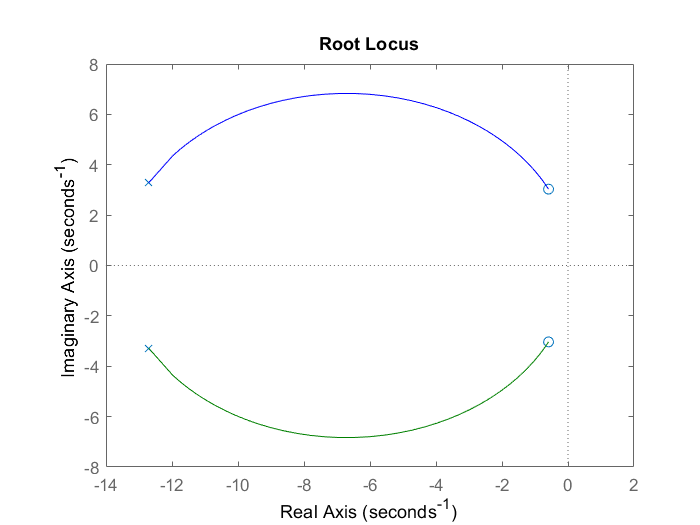

rlocus(controlador)

Es entonces que se puede realizar la simulación del controlador y la planta a lazo cerrado.

%Simulación 
pos_mot


pos_mot =
 
            48.8
  -------------------------
  s^3 + 5.163 s^2 + 15.58 s
 
Continuous-time transfer function.



G_final=feedback(controlador*pos_mot,1)


G_final =
 
               180.8 s^2 + 213.2 s + 1725
  ----------------------------------------------------
  s^5 + 30.58 s^4 + 319 s^3 + 1466 s^2 + 2897 s + 1725
 
Continuous-time transfer function.



pole(G_final)

ans =   -15.0000
   -5.0000
   -5.0000
   -4.5703
   -1.0067


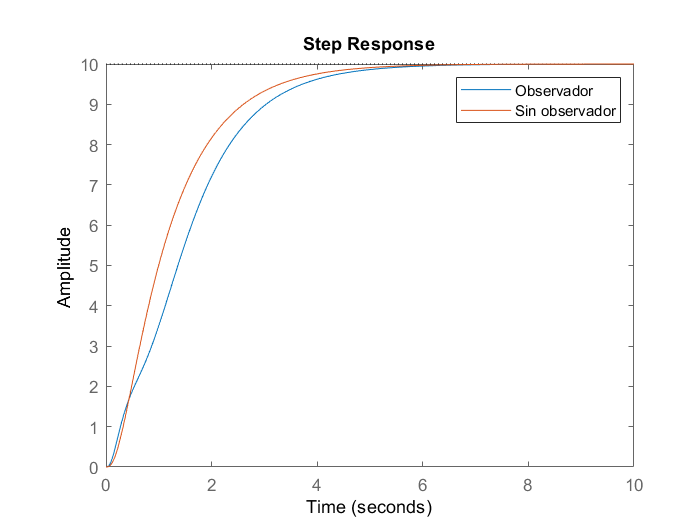

step(10*G_final,10)
hold on
step(10*sys,10)
hold off
legend('Observador','Sin observador')

stepinfo(G_final)

ans = struct with fields:
        RiseTime: 2.7577
    SettlingTime: 4.6305
     SettlingMin: 0.9002
     SettlingMax: 0.9997
       Overshoot: 0
      Undershoot: 0
            Peak: 0.9997
        PeakTime: 8.6556


Finalmente, se puede observar que los polos a lazo cerrado son todos los que se habían asignado.

pole(G_final)

ans =   -15.0000
   -5.0000
   -5.0000
   -4.5703
   -1.0067


## 3.4 Simulación en Simulink

En este caso es útil realizar la simulación en Simulink de MATLAB, ya que este nos va a permitir ver la señal de control, de error, y nos va a permitir tomar en cuenta no-linealidades como la saturación (0V - 10V) la zona muerta del conjunto variador-motor (2.14V) en la simulación para realizar las correcciones necesarias.

Para simulink continuo:

[num_c,den_c]=tfdata(controlador);
num_c=cell2mat(num_c);
den_c=cell2mat(den_c);

[num_p,den_p]=tfdata(pos_mot);
num_p=cell2mat(num_p);
den_p=cell2mat(den_p);

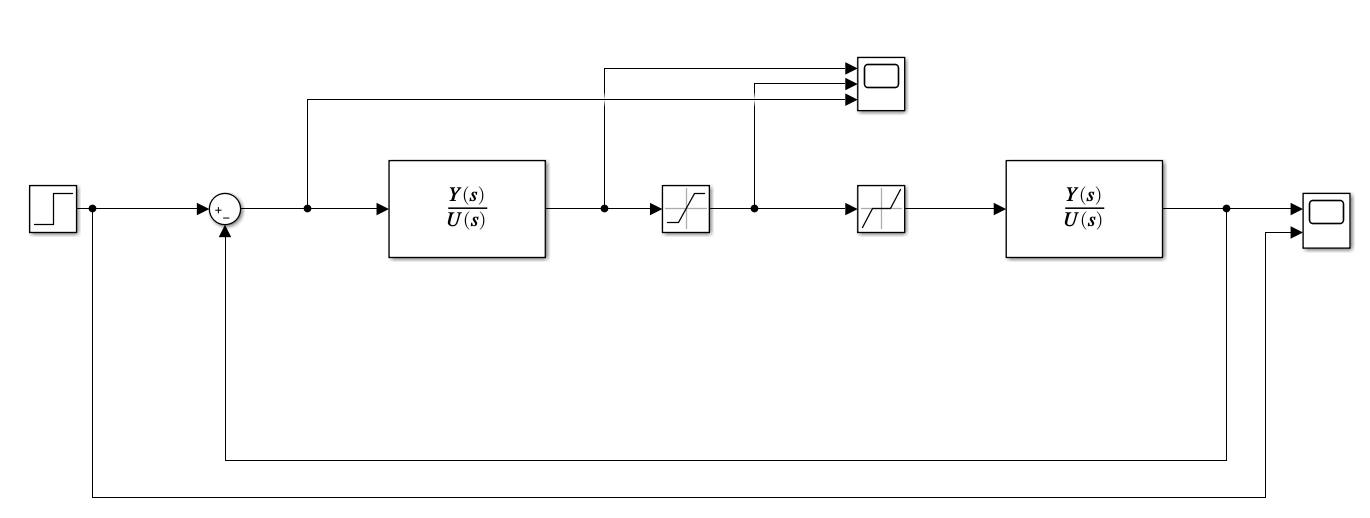

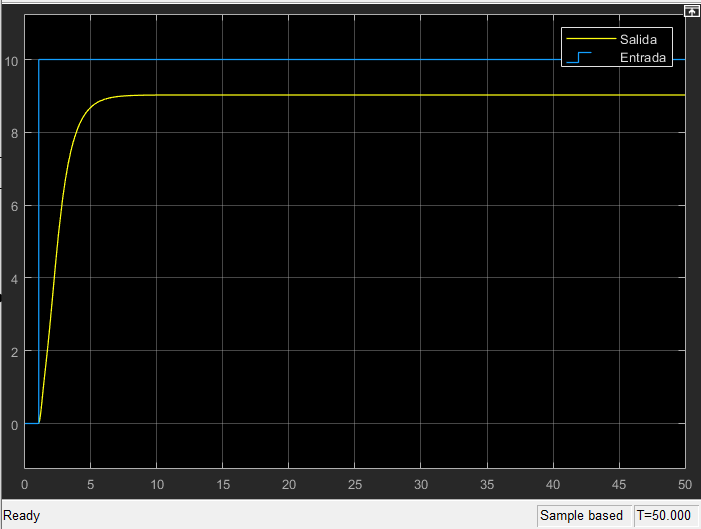

Como se puede ver, las no-linealidades provocan un error en estado estacionario, en concreto este error es provocado por la zona muerta del variador-motor, para compensar este problema se puede agregar una pequeña ganancia de pre-compensación adicional, esta ganancia se obtiene como una bastantante pequeña de 1.1, es en la simulación suficiente para compensar el error en estado estacionario. 

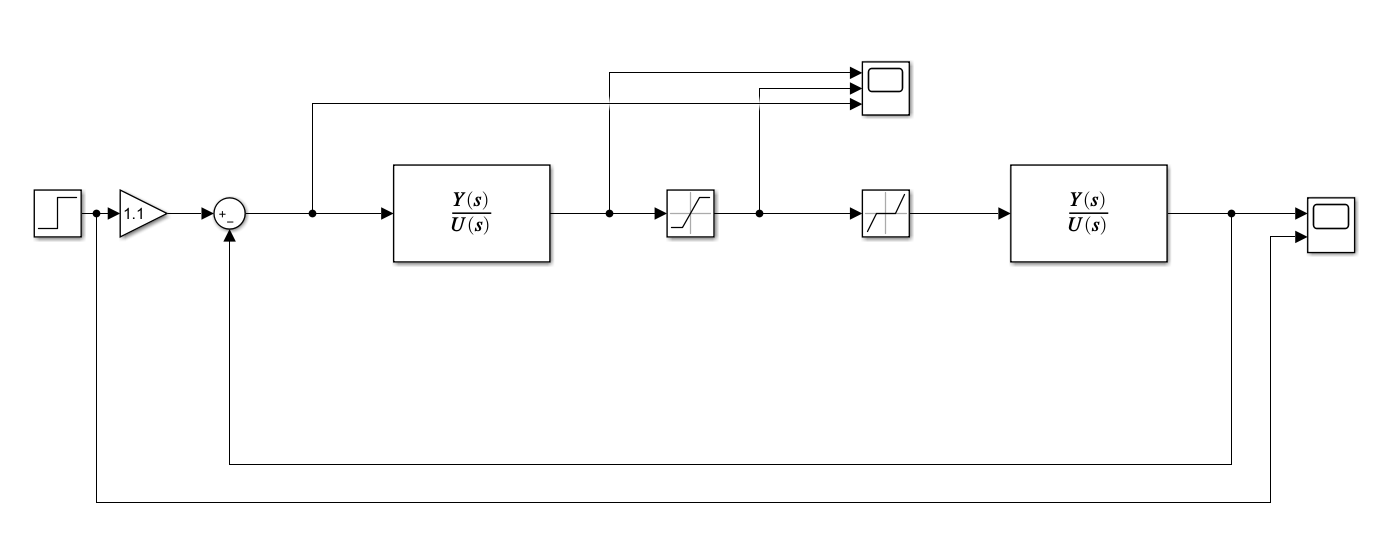

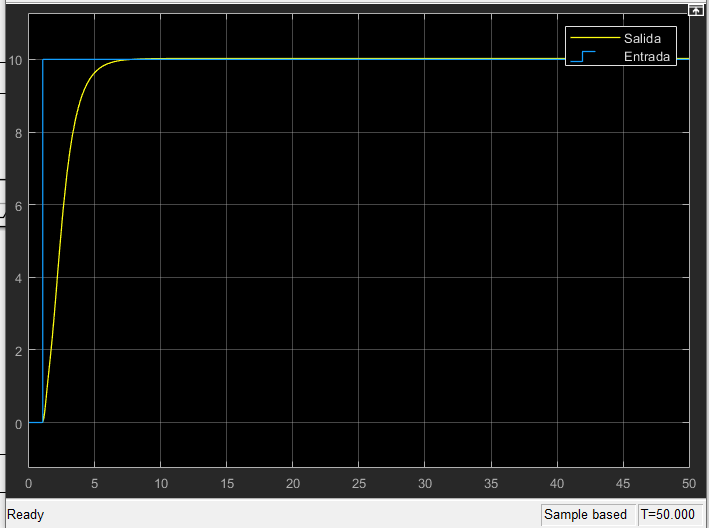

# 4. Discretización

Como se mostró hasta ahora, el controlador se ha diseñado en tiempo continuo, bien podría haberse diseñado en tiempo discreto, pero en esta ocasión se optó por diseñarlo en tiempo continuo y luego discretizar. 

## 4.1 Discretización de la planta 

En primer lugar, se debe discretizar la planta, para ello se debe determinar el periodo de muestreo, para esto, se puede obtener un periodo de muestreo mediante el siguiente criterio aproximado:


$$\omega_s =N_m *\omega_m \;\;\;\;\;\;\;\;\;\;\;\;20\le N_m \le 50$$


Donde:

$\omega_m$: Ancho de banda del sistema a lazo cerrado.

$N_m$: Número entero comprendido entre 20 y 50

wm=bandwidth(feedback(pos_mot,1))

wm = 4.6517

Nm=50;
Ts=2*pi/(wm*Nm)

Ts = 0.0270

Lo que redondeando es:

Ts=27e-3

Ts = 0.0270

Realizando la discretización con un retenedor de orden cero:

pos_mot_discreto=c2d(pos_mot,Ts,'zoh')


pos_mot_discreto =
 
  0.0001546 z^2 + 0.000597 z + 0.0001442
  --------------------------------------
    z^3 - 2.859 z^2 + 2.729 z - 0.8699
 
Sample time: 0.027 seconds
Discrete-time transfer function.



[num1,den1]=tfdata(pos_mot_discreto);
num1=cell2mat(num1)

num1 = 	1.0e+-3 *

         0    0.1546    0.5970    0.1442


den1=cell2mat(den1)

den1 =     1.0000   -2.8593    2.7292   -0.8699


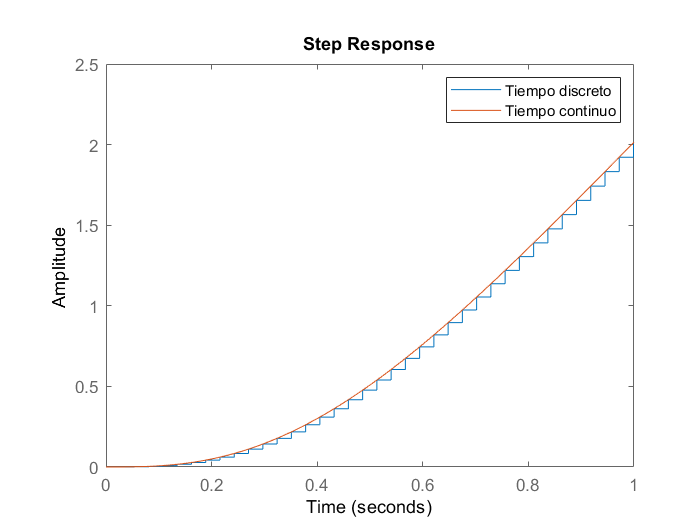

step(pos_mot_discreto,1)
hold on
step(pos_mot,1)
hold off
legend('Tiempo discreto','Tiempo continuo')

## 4.2 Discretización del controlador

Con el modelo de la planta discretizado, se puede seguir con la discretización del controlador, a diferencia del modelo de la planta, el controlador se va a discretizar con la transformada bilineal:

controlador_discreto=c2d(controlador,Ts,'tustin')


controlador_discreto =
 
  2.743 z^2 - 5.381 z + 2.657
  ---------------------------
    z^2 - 1.409 z + 0.5008
 
Sample time: 0.027 seconds
Discrete-time transfer function.



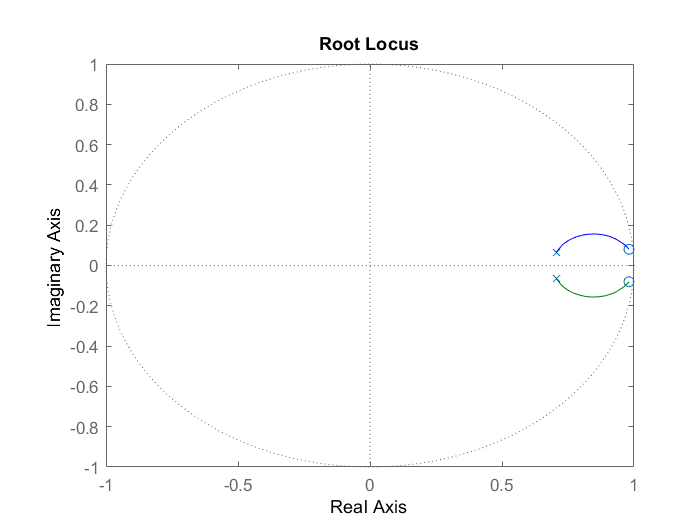

rlocus(controlador_discreto)

Ahora se debe obtener la función de transferencia a lazo cerrado para poder realizar la simulación ante la entrada escalón, para ello nos basamos en el siguiente diagrama de bloques:

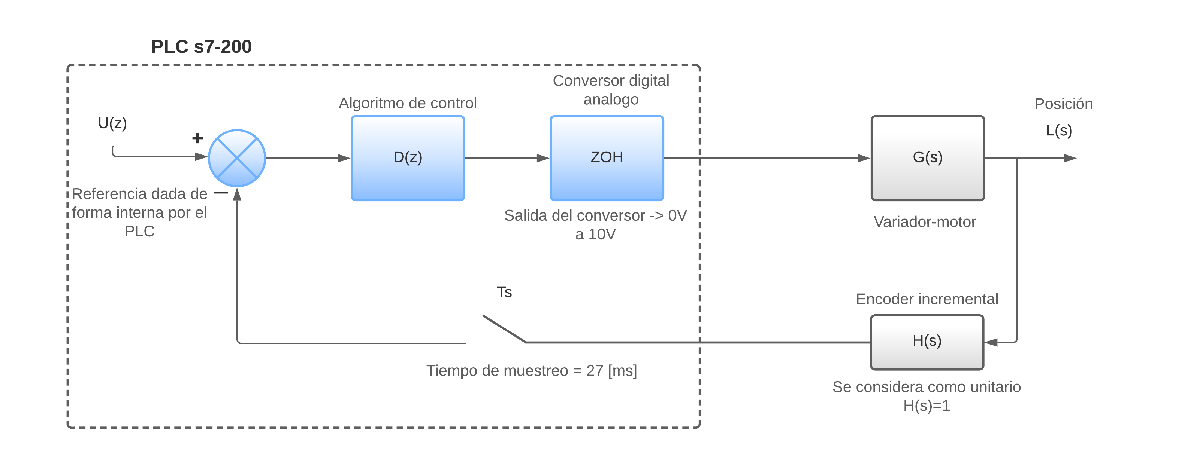

De este diagrama de bloques podemos obtener la siguiente función de transferencia a lazo cerrado:


$$\frac{L_{\left(z\right)} }{U_{\left(z\right)} }=\frac{D_{\left(z\right)} \bar{\textrm{GZO}H_{\left(z\right)} } }{1+D_{\left(z\right)} \bar{\textrm{HGZO}H_{\left(z\right)} } }$$
      

Y para simplificar tomamos el bloque de la planta y del retenedor de orden cero como uno solo, ademas, se tomara la realimentacion H(z) como unitaria:


$$\frac{L_{\left(z\right)} }{U_{\left(z\right)} }=\frac{D_{\left(z\right)} G_{\left(z\right)} }{1+D_{\left(z\right)} G_{\left(z\right)} }$$
      

G_final_discreto=feedback(controlador_discreto*pos_mot_discreto,1)


G_final_discreto =
 
  0.000424 z^4 + 0.0008058 z^3 - 0.002407 z^2 + 0.0008106 z + 0.0003831
  ---------------------------------------------------------------------
       z^5 - 4.268 z^4 + 7.261 z^3 - 6.151 z^2 + 2.594 z - 0.4352
 
Sample time: 0.027 seconds
Discrete-time transfer function.



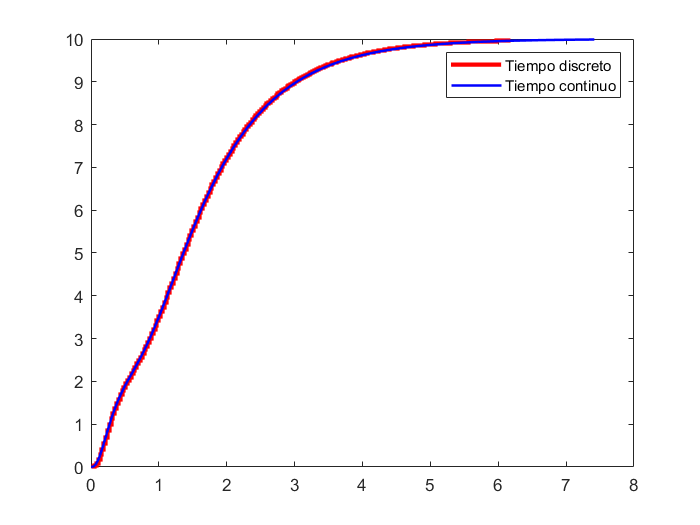

[y1,t1]=step(10*G_final_discreto);
stairs(t1,y1,'r','LineWidth',2.5)
hold on
[y2,t2]=step(10*G_final);
plot(t2,y2,'b','LineWidth',1.5)
hold off
legend('Tiempo discreto','Tiempo continuo')

## 4.3 Simulación en Simulink

Tal como en el caso de tiempo continuo, se realizará una simulación en Simulink para revisar los efectos de dos no-linealidades, y tal como en tiempo continuo se utilizara una ganancia de pre-compensación adicional

Para simulink discreto:

[num,den]=tfdata(controlador_discreto);
num=cell2mat(num);
den=cell2mat(den);

a=num(1);
b=-num(2);
c=num(3);
d=den(1);
e=-den(2);
f=den(3);

[num1,den1]=tfdata(pos_mot_discreto);
num1=cell2mat(num1);
den1=cell2mat(den1);

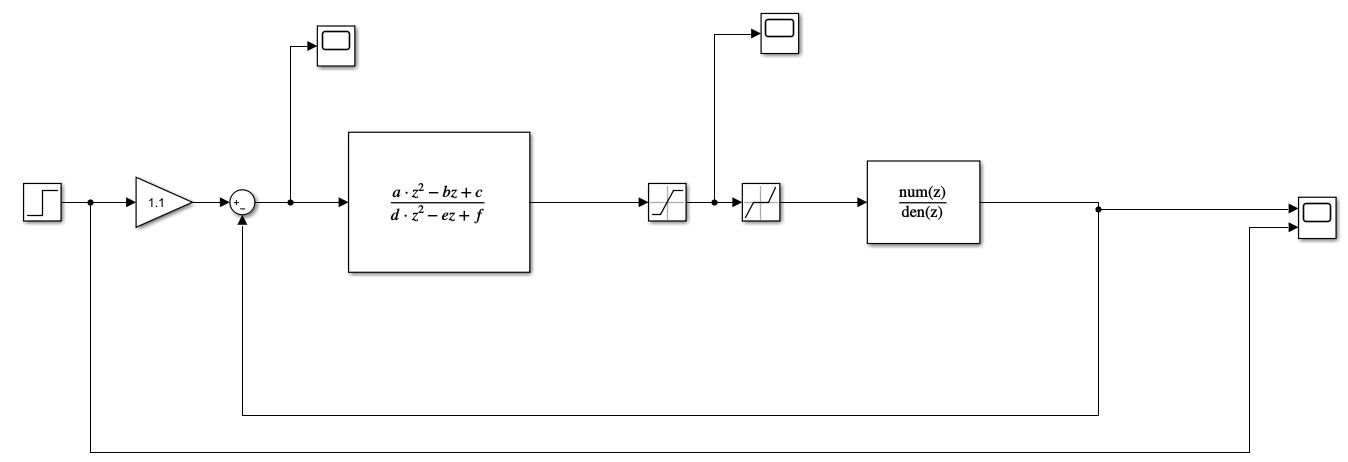

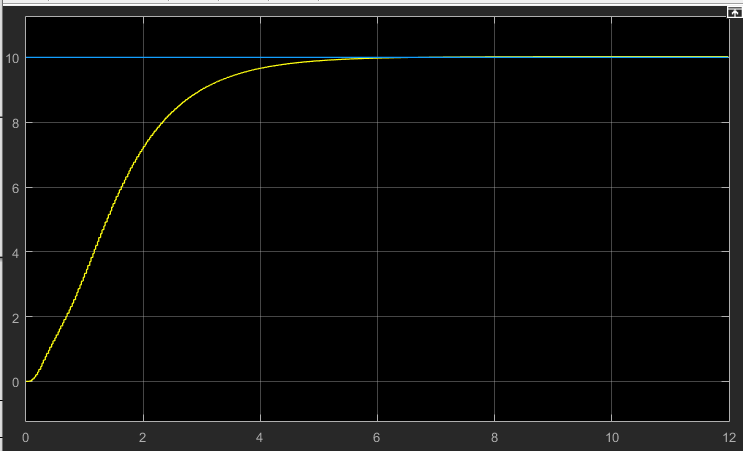

# 5. Contrastar datos con la simulación

En este caso se implementó el controlador en tiempo discreto en el PLC S7-200, entonces, se pudo obtener, mediante el uso de la instrumentación específica (osciloscopio), la señal de control proveniente de la salida analógica del PLC (DAC) y se puede comparar con la simulación de la señal de control obtenida con Simulink:

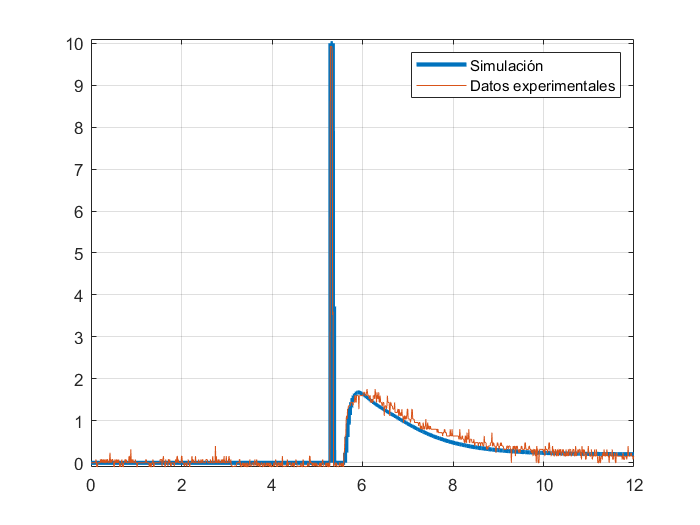

Vs=2; %escala vertical del osciloscopio
Tsampling=1e-2;
clear to
to(1)=0;
for i=2:length(Source)
    to(i)=to(i-1)+Tsampling;
end
plot(simout.time,simout.signals.values,'LineWidth',2.5)
hold on
ta=find(to>=12);
plot(to(1:ta(1)),Source(1:ta(1))*Vs/25)
axis([0 12 -0.1 10.1])
grid on
hold off
legend('Simulación','Datos experimentales')

También se pudo tomar datos experimentales de la velocidad, para obtener estos datos el procedimiento es el mismo que se siguió para obtener los datos que fueron usados para estimar la función de transferencia original.

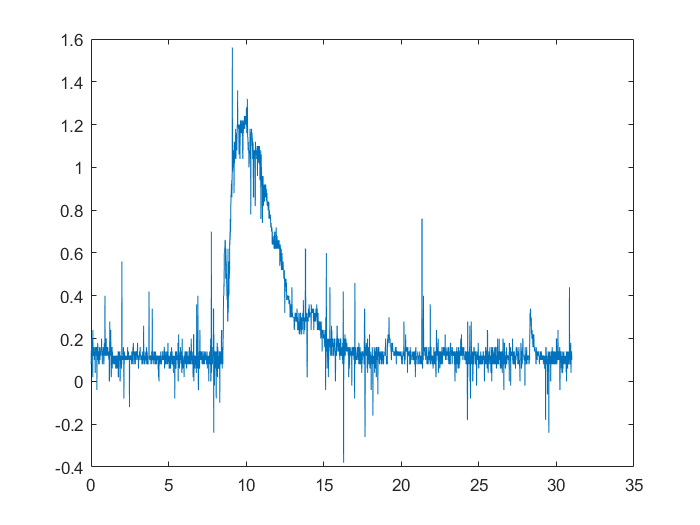

Ts=1e-2;
fs=1/Ts;
Vs=5e-1;
t(1)=0;
for i=2:length(Source1)
    t(i)=t(i-1)+Ts;
end
data=Source1*Vs/25 -0.5;
plot(t,data)

Como se puede observar, los datos deberían filtrarse, para ello con un filtro digital Butterworth:

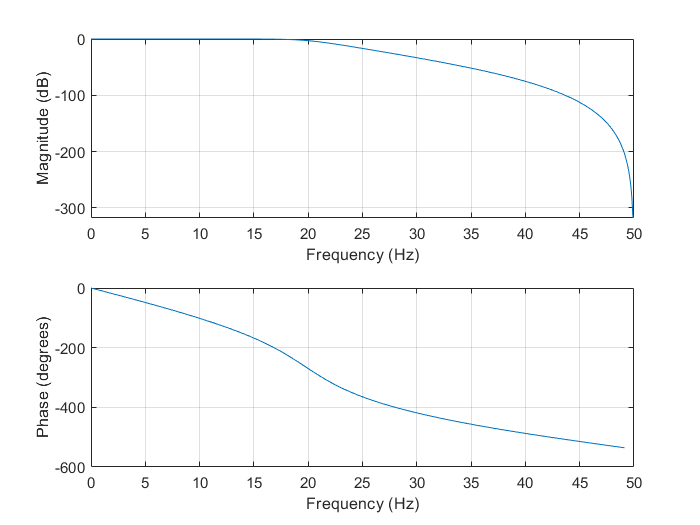

fc=20;
[num,den]=butter(6,fc/(fs/2));
freqz(num,den,[],fs)

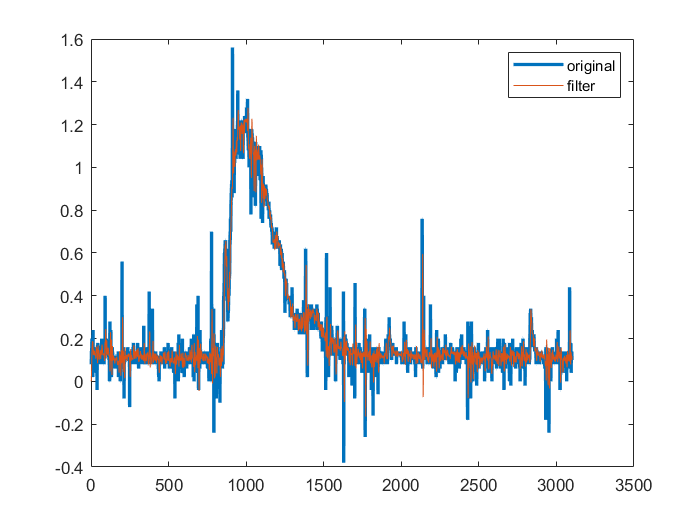


DataOut=filter(num,den,data);

plot(data,'LineWidth',2)
hold on

plot(DataOut)
hold off
legend('original','filter')

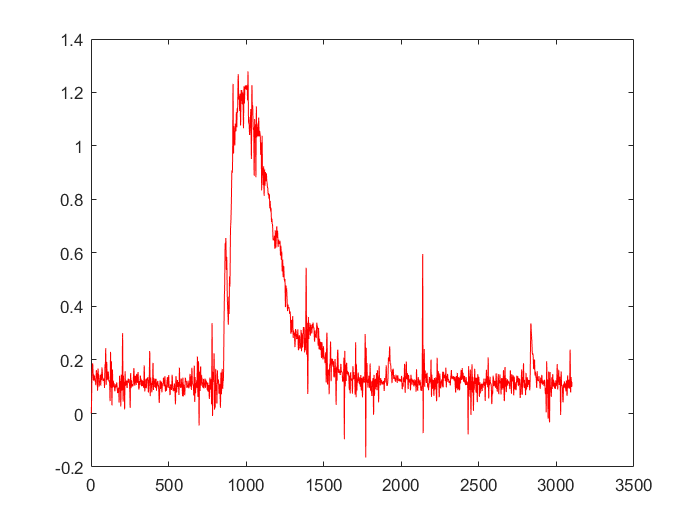


plot(DataOut,'r')

Escalando esta medida para obtener la curva en términos de unidades de velocidad lineal (cm/seg) y comparando con la simulación:

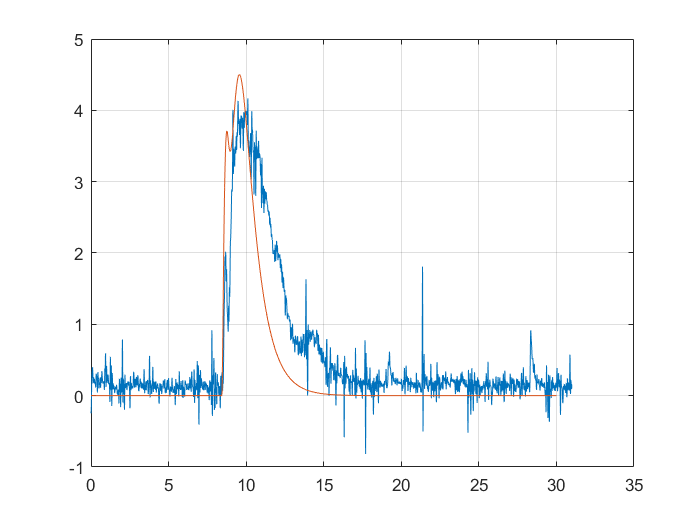

vel_exp=DataOut*pi*1.1962e3/200*(1.8382/10);
plot(t,vel_exp-0.25)
hold on
plot(simout1.time,simout1.signals.values)
grid on
hold off

Se observa que en este caso existe una mayor diferencia entre la simulación de la velocidad (variable de estado X2) que en el caso de la señal de control. Esto se puede deber a más no-linealidades que no se han considerado en la simulación de Simulink.

Adicionalmente, en Simulink se puede integrar esta velocidad medida, esto para comparar de forma aproximada la posicion:

dataout=timetable(seconds(t(1:3000)),vel_exp(1:3000)-0.41);    %exportar datos de Worksapace a Simulinnk

Obteniendose:

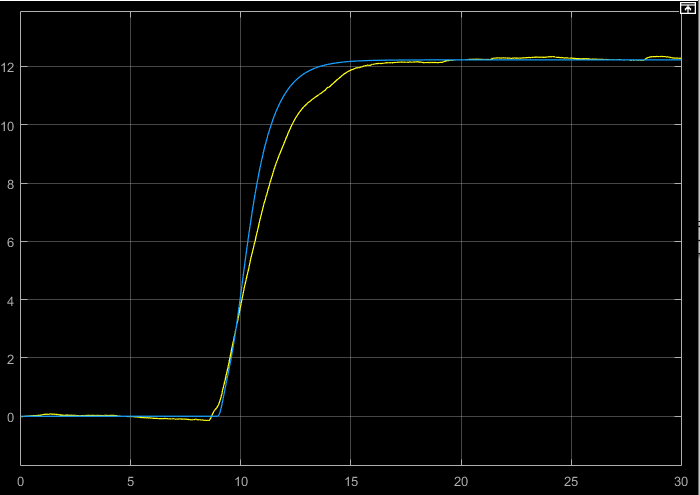

Se puede observar que, en efecto, hay variaciones con respecto de la simulacion. Estas variaciones, como ya se menciono, puede deberse a las alinealidades que no se llegaron a considerar, impresiciones en el modelo utilizado para el diseño y simulaicones. Para nuestros propositos esta puede ser una respuesta aceptable, esto ya que el error en estado estacionario es practicamente de cero y el tiempo de asentamiento es aproximadamente el deseado. En caso de requerirse mas precision en el tiempo de asientamiento, se puede realizar un rediseño de las ganancias de realimentacion K.

# 6. Referencias 

[1] J. H. Braslavsky, *Notas de Clase Control Automático 2*, Universidad Nacional de Quilmes, 2001

[2] K. Ogata, *Ingeniería de control moderna*, 5a. ed. Madrid: Pearson Educación, 2010.  

[3] H. Immaneni, *Mathematical modelling and position control of brushless dc (BLDC) motor*, International Journal of Engineering Research and Applications, vol. 3, no. 3, pp. 1050-1057, 2013.